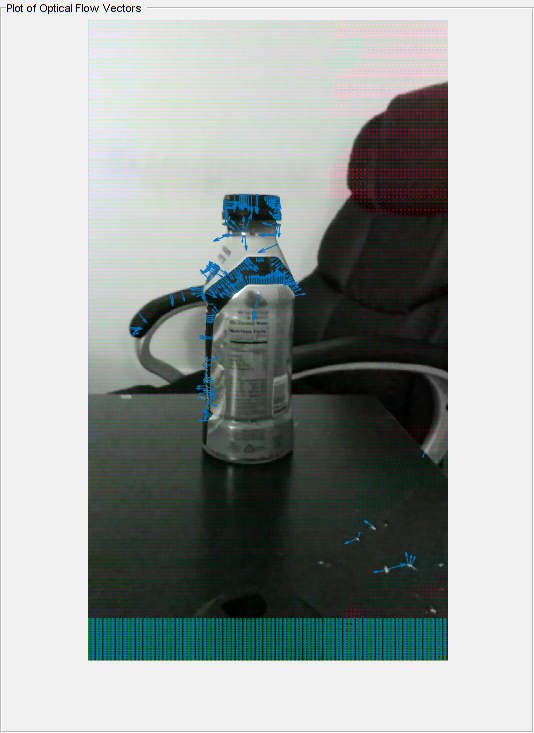

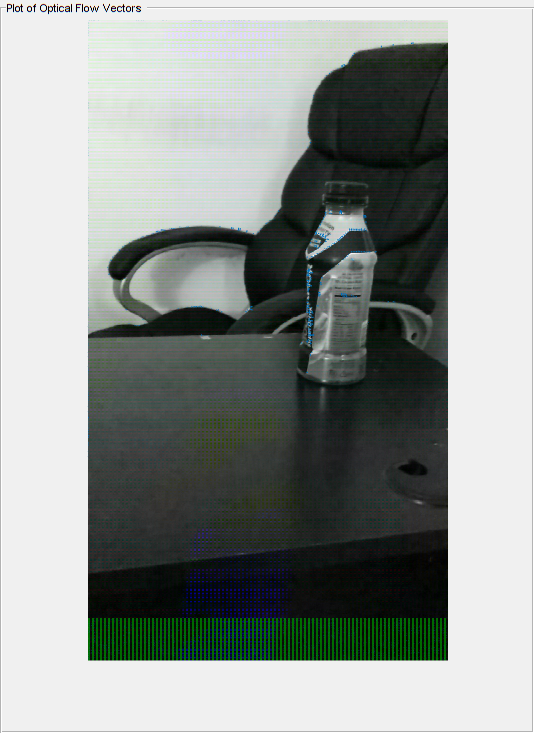

%https://drive.google.com/open?id=1KErmYuIzHEjbCFR5mLCdNezspqcBkQPW

%PART A
%Create a folder to store the frames as images
%{
workingDir = 'C:\Users\bengo\Downloads';
mkdir(workingDir)
mkdir(workingDir,'images')
%}

%Reads video
vidReader = VideoReader('C:\Users\bengo\Downloads\test1.mp4','CurrentTime',0);

opticFlow = opticalFlowLK('NoiseThreshold',0.009);

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

%ii = 1;

%Reads video as frames and each frame as an image
while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = rgb2gray(frameRGB);
    flow = estimateFlow(opticFlow,frameGray);
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
    %This was to make the video with the plot
    %Saved the figure as a jpg file and named it
    %{
    filename = [sprintf('%03d',ii)];
    fullname = fullfile(workingDir,'images',filename);
    print(fullname, '-djpeg')
    ii = ii+1;
    %}
    hold off
    pause(10^-3)
end

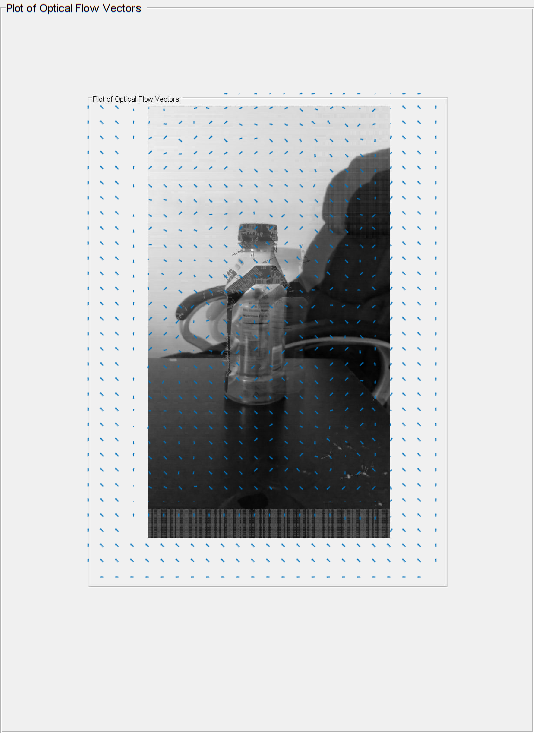

%Code used to mesh the images together for the video
%{
imageNames = dir(fullfile(workingDir,'images','*.jpg'));
imageNames = {imageNames.name}';

outputVideo = VideoWriter(fullfile(workingDir,'test1_out.avi'));
outputVideo.FrameRate = vidReader.FrameRate;
open(outputVideo)

for ii = 1:length(imageNames)
   img = imread(fullfile(workingDir,'images',imageNames{ii}));
   writeVideo(outputVideo,img)
end

close(outputVideo)
%}


%PART B
%Prepping the image
img1 = im2double(rgb2gray(imread('C:\Users\bengo\Downloads\001.jpg')));

%Getting object ready
hbm = vision.BlockMatcher('ReferenceFrameSource',...
        'Input port','BlockSize',[35 35]);
    
hbm.OutputValue = 'Horizontal and vertical components in complex form';
halphablend = vision.AlphaBlender;

%Prepping comparison image
img2 = im2double(rgb2gray(imread('C:\Users\bengo\Downloads\092.jpg')));

%Calculate motion
motion = hbm(img1,img2);

%Merge images
img12 = halphablend(img2,img1);

%Show and plot motion
[X,Y] = meshgrid(1:35:size(img1,2),1:35:size(img1,1));         
imshow(img12)
hold on
quiver(X(:),Y(:),real(motion(:)),imag(motion(:)),0)
hold off